clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


Define linear systems

decoupledSys = ss(param.model.A, param.model.B_Bar, eye(12),0);
coupledSys = ss(param.model.A, param.model.B, eye(12),0);

Define simulation parameters

simtime = 10*60;
steptime = 200;
u = [zeros(4,steptime), ones(4,simtime-steptime)];
t = linspace(0,simtime,length(u));

Simulate

y = lsim(decoupledSys,u,t);
Ta_decoupled = [y(:,2),y(:,5),y(:,8),y(:,11)];
y = lsim(coupledSys,u,t);
Ta_coupled = [y(:,2),y(:,5),y(:,8),y(:,11)];

Plot

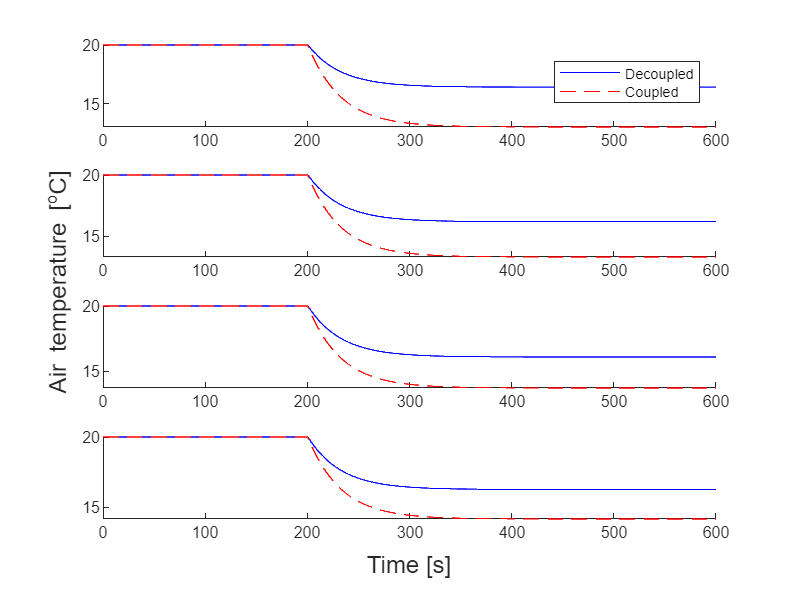

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(t,20 + Ta_decoupled(:,i),'blue')
    plot(t,20 + Ta_coupled(:,i),['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Air temperature [^{o}C]')

saveas(gcf,'../Images/Openloop_step_comparison','epsc')